# RUSLE erosion 

In this script we'll calulate current soil erosion rates for southwestern Germany and have a look at which areas are under threat. We'll compare the modelled erosion rates to rates of sediment transport in local rivers to see what happens with the eroded material.

clc
clear
close all

### Load your data

DEM =  % load DEM
DEM.Z(end,:)= 2000;                  % condition DEM that streams don't flow south
Kfactor = % load K (erodibility)
Pfactor = % load P (support practices)
Cfactor = % load C (vegetation cover)

Most data I've downloaded at the European Soil Data Centre. [ESDAC - European Commission](https://esdac.jrc.ec.europa.eu/)

### Visualize data

Let's have a look at the data we have so far. Plot the 4 rasters in a 2 by 2 figure as in the previous excercise.

figure()
set(gcf,'Units','normalized','Position',[0.05 0.05 0.9 0.9],'Visible','on'); 
tiledlayout(2,2)
nexttile
% plot DEM
% plot K,P, and C factors with proper labels etc

Questions:

- What do higher and lower for the different factors mean?

- How are the different factors related to the landscape and geology we've dicussed in P1?

- Why do the rasters have no-data values?

- Do some rasters look like there might be problems in the data calculation?

P-factor calculation:

P = *Pc*Psw*Pgm*

where *Pc* is the contouring sub-factor for a given slope of a field, and *Psw* is the stone walls sedimentation sub-factor (known as terrace sub-factor) and *Pgm* is grass margins sub-factor (known as strip cropping sub-factor and buffer strips). P-factor based on 270'000 ground observations that were used in spatial interpolation (kriging).

### R factor

The rainfall erosivity is often approximated locally from the mean annual precipication. Higher precipitation, higher rainfall erosivity. Following the German Industry standaard DIN19708, we calculate erosivity as

*R* factor = 0.0833 × MAP + 1.73  

MAP—mean annual precipitation.

MAP = % load MAP data

As you see, we get a warning because the loaded precipitation raster is in WGS-84 coordinates. Reproject the raster to UTM coordinates with 500m resolution for our calculations ('reproject2utm')

MAP =

Now, let's calculate the R-factor with the above equation from the mean annual precipitation.

Rfactor =

### L Factor

Next up is the L-factor, which quantifies the hillslope length for every pixel. Basically, this is a metric that calculates for every pixel how long the uphill part of the hillslope is. The assumption is that the farther down on a hillslope to more water has accumulated to start eroding away your soil. Is this a good assumption?

For this, we need our flow accumulation grid. However, we only care about the hillslope portion of the flow accumulation. Rivers would have huge flow accumulation numbers compared to hillslopes and would therefore result in enormous erosion rates. Schmidt et al. 2019 suggesting to use a maximum 100m hillslope length in the Alps. However, flow accumulation is defined in units of area and not length. Therefore, we can instead assume a that areas accumulating more than 100 x 100 m should start forming gullies and can therefore be taken as a maximum accumulation value.

Athres = 1e5; % 100x100m threshold of flow accumulation at which rivers starts flowing and there's no more hillslope
FD = 
A  = 
A  = % convert flow accumulation from cells to meters 
A.Z(A.Z > ...  % set all values in A, that are above Athres to Athres

Here's the equation for the slope length factor from Schmidt et al. 2019

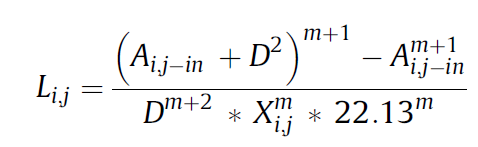 

A — flow accumulation at cell i,j; D — cell size of DEM; Xi,j — sin(alpha) * cos(alpha) where alpha is the aspect of the grid cell (i,j).

and

with

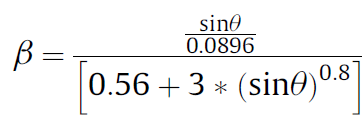

where theta is slope of cell i,j in degree. Now let's put all of these equations into code and calculate the necessary variables (slope, aspect).

slope  =      % slope in degree
aspect_grid = % aspect of slope

beta   = (abs(sin(slope.Z))./0.0896) ./ (0.56 + 3.*abs(sin(slope.Z)).^0.8);
% note how I use a '.' before the multiplication, division, and power signs. This
% means that these operations are performed element-wise and not like in
% standard matrix multiplication (rows * columns).

% I use the absolute values of sinus abs(sin(x)) to avoid negative values.

% I also used only the Z-matrix of the slope. So, we only calculate the
% values as a matrix, not as a GRIDobj. That is because such complicated
% operations are not possible on GRIDobjs

m =        % the ratio of rill and interrill erosion

Lfactor = DEM*nan;  % make empty DEM copy that we can fill with values
Lfactor.Z = % type equation for L-factor here. Use dots in front of 
% mulitplication/division/power. use the absolute values of cos() and sin()

### S-factor

For the S-factor, the empiric function proposed by McCool et al 1987 is comonly used to determine the slope steepness factor in the Revised Universal Soil Loss Equation (RUSLE). McCool 1987 differentiate the relation between soil loss and slope steepness in radians (s) with two functions. One for slopes with an inclination less than 9% and the other greater or equal 9%. The functions are as follows:

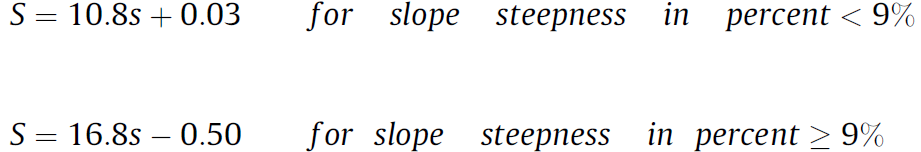 s = sin(theta)

S_low = DEM*nan; % make empty GRIDobjs
S_high= DEM*nan;
S_low.Z  =       % for slopes below 9%
S_high.Z =       % for slopes above 9%

high_slope_condition = % make conditional raster for slopes > 9 degree; 

Sfactor = S_low;       % copy low slope raster
Sfactor.Z(high_slope_condition.Z) =  % modify values for high slopes

### Align rasters

Most of your raster have different resolutions. To easily multiply them, they fir.st neew to be made the same size and resolution. Use the  'GRIDobj/resample.m' function to make all rasters the same size and resolution as your DEM.

Kfactor = 
% do the sae for the other RUSLE factors

### RUSLE calculation

Let's calculate soil erosion rates for southwestern Germany.

SoilErosion % enter RUSLE euqation here

Plot the soil erosion rates and interpret the map. Where are hotspots and lowspots? What are the dominant factors driving soil erosion patterns in this region?

Use the 'plasma' color map and add a label for the unit of soil erosion (what was the unit again???)

A few high values limit the use of the color map, by making all the most values a similar color. Use the 'caxis' command to limit the color map between values of 1 and 100.

% plot again with caxis limits

### Can we compare our modelled map to data?

Suspedend sediment loads from rivers are a data set that we can compare our erosion rate to. Fine-grained material from hillslopes gets eventually washed into rivers. Therefore, in an ideal world, the suspended sediment yield in river should equal our soil erosion rates. Government agencies typically monitor the amount of sediment in rivers. Below is a map of sediment yield in rivers of southcentral Germany. 

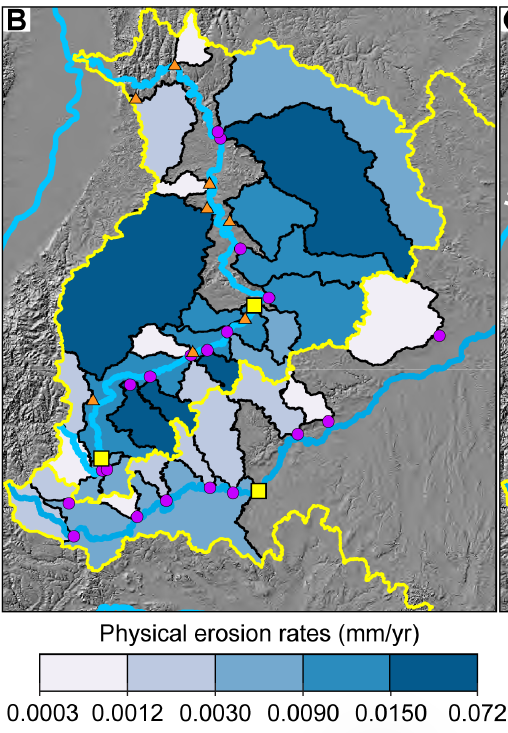 *Suspended sediment erosion data from Schaller et al. 2024*

How can we compare our erosion rate data to the sediment yields from this paper?

The answer to this question will be discussed in the lecture and/or can be found in the _key file.

### Fill raster NaNs

Our current soil erosion estimates have a bunch of NaN values for areas that have a lot of urban construction. This might lead to an underestimation of total erosion and therefore river sediment yield. We can fill in the NaN's in the Pfactor, by assuming that all NaN pixels do not have any erosion reducing measures. For the K-factor, we can interpolate the values from the exisiting maps using a Matlab interpolation algorithm.

First, let's fill in the NaNs of the P-Factor. What is the P-value for no erosion measure?

Pfactor_interp % copy P factor;
Pfactor_interp.Z   % set all no data points (NaNs) to the value for no erosion measure. Use the function 'isnan'to find NaN values

The interpolation for the K-factor is more complicated. We need to identify the coordinates of no-nan values, create an interpolation and then query the K values for the nan pixels. 

Kfactor_nonan     = % values that are not nan in the Kfactor Z matrix. isnan finds NaN.
% You can do the opposite by putting a ~ in front of your command
[x_nonan,y_nonan] = ind2coord(Kfactor,find(Kfactor_nonan));   % get coordinates of NaNs in Kfactor
z_nonan = Kfactor.Z(~isnan(Kfactor.Z));                       % get Kfactor of no nan values 
interpol = scatteredInterpolant(x_nonan,y_nonan,double(z_nonan),'linear', 'none'); % run interpolation

nanMask = isnan(Kfactor.Z);   % make matrix the size of the Kfactor with nan values = true
[x_nan,y_nan] =  % find locations of nan values
Kfactor_interp = % copy Kfactor GRIDobj
Kfactor_interp.Z(nanMask) = interpol(x_nan,y_nan); % fill nan locations with interpolated values

Now that the P and K factors have been interpolated for nan areas, we can calculate soil erosion again for all areas.

SoilErosionInterp = % calculate with interpolated rasters;
% plot soil erosion with 'plasma' color map and limits on the color map

The remaining NaN areas are proper cities and towns and are probably not contributing much sediment, so we can ignore them.

### Load suspended sediment data

data = readtable('../data/Schaller2024_Table1.xlsx','VariableNamingRule','preserve','Sheet',2)

Columns with PER (physical erosion rate) contain the suspended sediment erosion rates. PER2 is the measured suspended sediment erosion rate. PER3 represents the measured suspended sediment erosion rate plus an esimate of bedload sediment transport in the river.

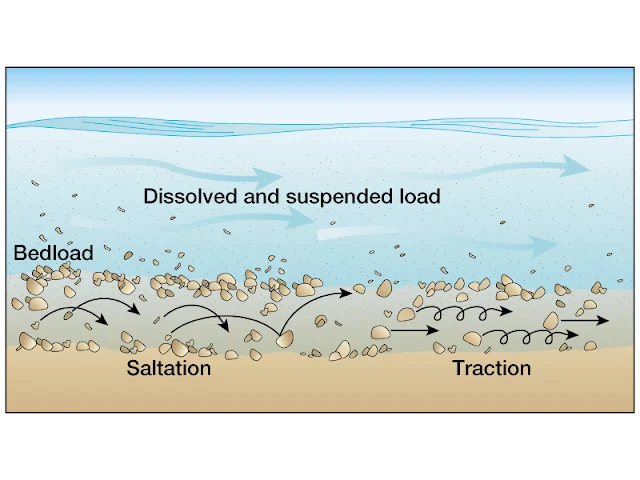 *Image from GeologYin.com*

Let's plot the DEM with the stream network and the stations. You can use the normal plot command and x and y utm cooridnates to plot the gauging stations. 

[x,y] = % use the ll2utm function to convert the station coordinates to UTM

S = % make stream network with 5km² minimum drainage area
% plot DEM
% plot streams
% plot stream gauge locations, use 'MarkerFaceColor' and 'MarkerEdgeColor'
% and the Matlab marker abbreviations found at the bottom of this help page
% https://nl.mathworks.com/help/matlab/creating_plots/create-line-plot-with-markers.html
% make the markers look nice

% here are the matlab color commands
% https://nl.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html

### Snapping streams

If you zoom into the map above, you'll notice that the stream gauges are not directly located on the stream pixels. However, we want to delineate the drainage basins for our stations. For this, we need to snap the locations to the stream network ('snap2stream'). Use the visual check, to see if the snapping worked fine.

[xsn,ysn,ix] = % snap 2 streams and keep the x,y coordinates of the snapped streams as well as the ix - linear index into DEM of pixel

Ok, lets delineate the drainage basins with our new linear indices and the drainage basin function ('drainagebasins') and linear indices of snapped stream gauges.

DB 

We can convert the drainage basin raster to polygons for later export in GIS or to only display outlines in a map

DBstruct = GRIDobj2polygon(DB);
figure()
% plot DEM
% plot streams
% plot stream gauge locations
mapshow(DBstruct,'FaceColor','none','EdgeColor','k','LineWidth',1.5)   % plot outlines of catchments

We can calculate some metrics for our basins. E.g., drainage area, mean slope, and mean elevation. I've already added the command for the elevation statistics and you can add slope.

DBstats = drainagebasinstats(FD,ix, 'elevation', DEM);

One thing to check is whether we snapped the stream gauges to the correct streams. The data table contains an area column with the reported drainage area of every station. let's extract the drainage area from our drainage basin statistics and compare it to the reported values.

DBarea = vertcat(DBstats.upslopearea)/1e6; % DB area in km2, use vertcat to vertically assemble data from a data structure
figure()
% plot DBarea vs the drainage area from the data table as symbols (not
% line)
hold on
plot(xlim, ylim, '--r') % plot 1-1 line
xlabel('drainage area from DEM (km²)')
ylabel('drainage area from gauging station (km²)')

Some basins are far of the 1-1 line. In these cases the algorithm probably snapped to the wrong streams. Let's correct the coordinates of the affected streams 'Breg' and 'Steinlach'. This is a very annoying task, but very typical when working with data from government agencies and DEMs.

xsn(17) = % move x-coordinate of this stream 500 m east
 % move coordinates of stream 6 500m east and 800m south

% now snap the corrected coordinates again to the streams in the same
% manner as before

DB = % make drainage basins again with correct gauge locations

DBstats = % calculate statistics of drainage basins again
DBarea = % extract drainage basin area from DBstats structure and convert drainage basin area to km2
figure()
% plot DBarea vs the drainage area from the data table as symbols (not
% line)
% hold on
% plot 1-1 line
% add labels

This looks better. Now we can continue our analysis.

### Average soil erosion rate per basin

We can use 'drainagebasinstats' to calculate the mean erosion rates for our 'soil_erosion' and 'soil_erosion_interp' grids. Look into the help to figure out, how to do this.

ErosionStats = 

Now, we have erosion rates from RUSLE averaged for every basin. RUSLE soil erosion rates are in tons/ha/yr. The erosion rates from suspended sediment are in mm/yr using a density of 2.7 g/cm³. For comparison, we need to convert the RUSLE soil erosion rates into mm/yr.

density = 2.7;                                              % g/cm3
basinErosion = vertcat(ErosionStats.soil_erosion_mean);     % t/ha/yr
basinErosion = (basinErosion.*1e6)./(density.*1e8).*10;     % convert to mm/yr

basinErosionInterp = vertcat(ErosionStats.soil_erosion_interp_mean); % t/ha/yr
basinErosionInterp = (basinErosionInterp.*1e6)./(density.*1e8).*10;  % mm/yr

I debated if I should let you figure out the unit conversion yourself. Could you have done it on your own? Give it a try.

### Comparison of suspended sediment and soil erosion rates

Ok, now lets plot the comparison between RUSLE and suspended sediment rates. Make a 2 by 2 plot. In the first row, we compare the soil erosion rates  (normal and interpolated) versus the suspended sediment loads (data.PER2). In the second row, plot the soil erosion rates (normal and interpolated) versus the suspended sediment loads including an estimate of bedload transport (data.PER3).

Use circles as marker symbols ('o') and use 'MarkerSize' , 'MarkerFaceColor' , and  'MarkerEdgeColor' to make your plots look nice! Always add a 1-1 line, because our hypothesis is that they should be the same.

figure()
% soil erosion vs. PER2
% plot(0:1,0:1,'k--')  % 1-1 line

% soil erosion interpolated vs PER2

% soil erosion vs PER3

% soil erosion interpolated vs PER3

How do you interpret these findings? What's going on here? Why are these rates so far apart from each other?

- answers discussed during class and in _key file

Can you think of any negative effects, when large amounts of sediment get stored in catchments?

- answers discussed during class and in _key file

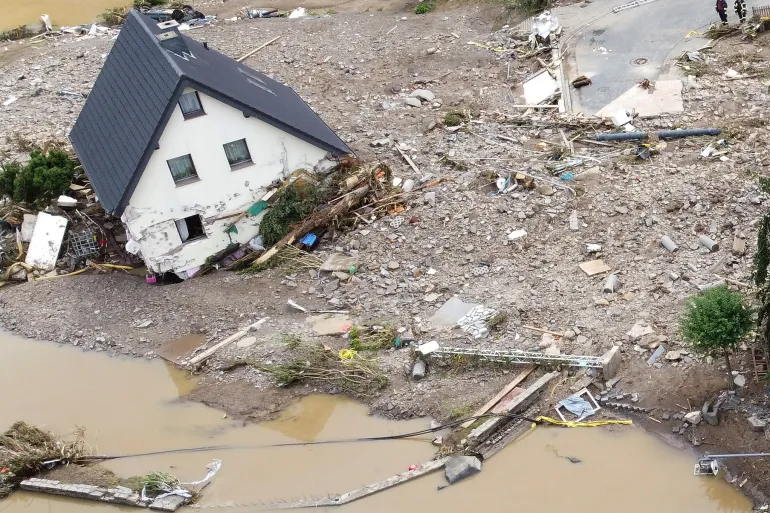 *House buried in sediment in Schuld, Germany [Reuters]*

Let's see if we see any spatial patterns in sediment connectivity—the ratio between the eroded material and the material exiting the catchment.

connectivity % make empty copy of DEM for connectivity raster
for i = 1:height(data)   % loop through catchments
    connectivity.Z(DB.Z == i) = % ratio between erosion from interpolated map and PER3 for this basin
end
figure()
% plot sediment connectivty raster
% plot catchment outlines on top of raster for appearance

Seems like rivers drainage south towards the Danube have a lower sediment connectivity. Why? Good question. 

Here's my untested hypothesis: These are limestone regions with inefficient surface drainage due to infiltration of water to the karst system. The loss of water to the groundwater system probably makes these regions less efficient at transporting hillslope sediment to the channels as exemplified by the many dry valleys in the region.

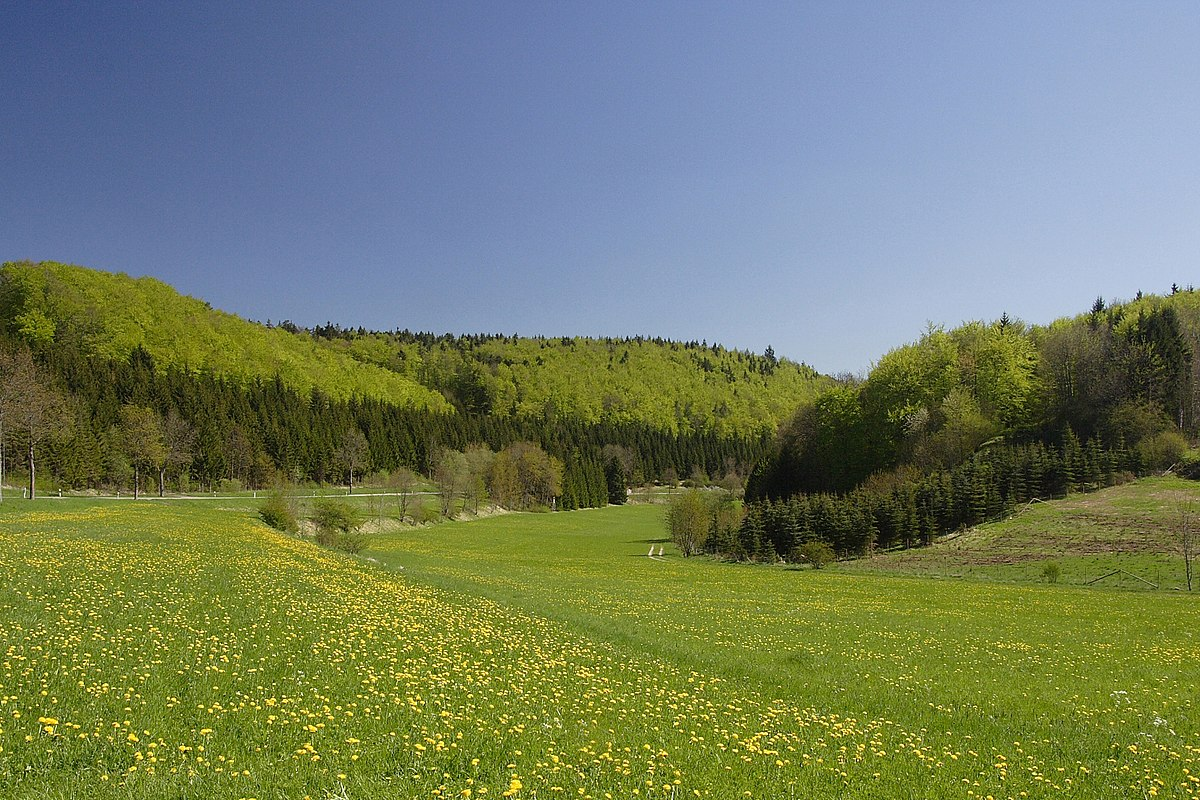*Valley without river (source: Wikipedia)*